% clear

### parameters

Fs = 1000;

### simulate & analyze beta event

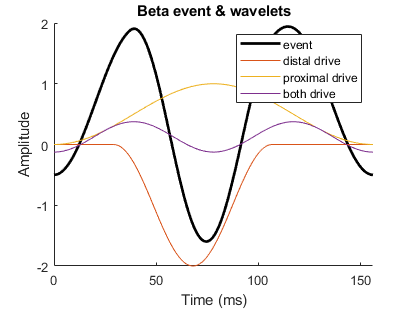

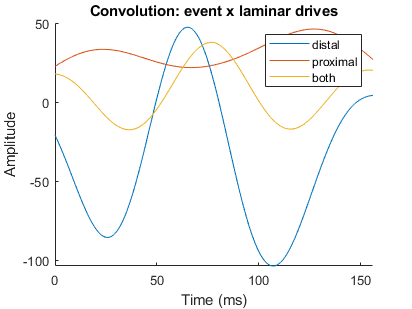

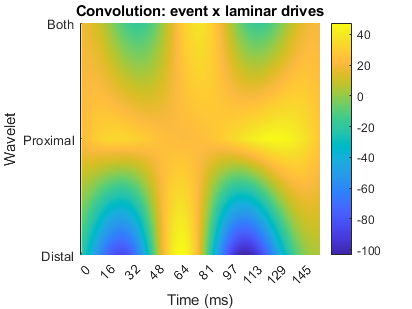

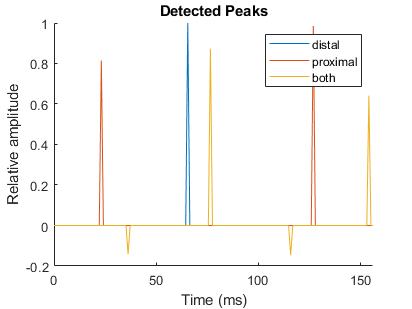

% generate semi-random beta event
event = sim_beta_event_rand(Fs);
% analyze simulated event
[rel_pk,w,wconv] = anaylze_beta_event(event,Fs,1);

### Other: CWT and STFT

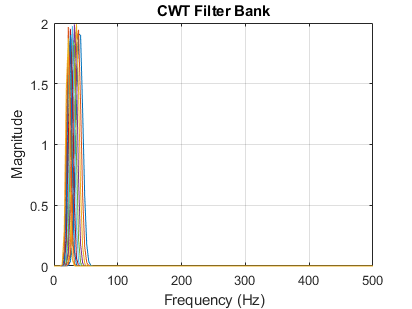

%% plot cwt of event
% create filter bank
fb = cwtfilterbank(SignalLength=numel(event),SamplingFrequency=Fs,...
     FrequencyLimits=[0 40]);
figure; freqz(fb)

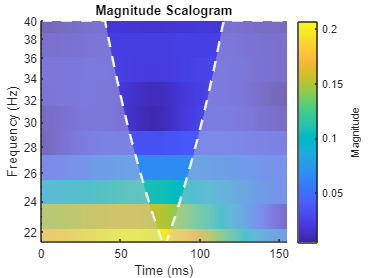

% run cwt
wt = cwt(event,FilterBank=fb); cwt(event,FilterBank=fb)

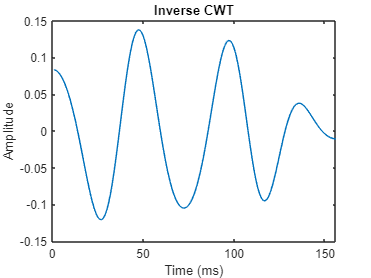

% plot inverse cwt
iwt = icwt(wt);
plot(iwt); title('Inverse CWT'); xlabel('Time (ms)'); ylabel('Amplitude')

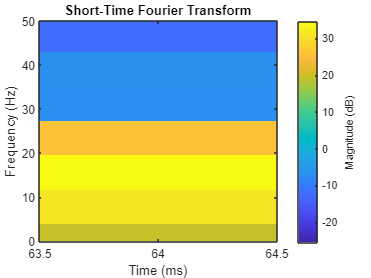


% plot stft of event
stft(event,Fs,'FrequencyRange','onesided'); ylim([0 50])